%LQR CONTROL DECENTRALIZADO
clc; close all; clear all;
 m1 = 0.75;
 m2 = 0.5;
 k1 = 100;
 k2 = 100;
 p1 = 80;
 p2 = 50;
A = [0 0 1 0;0 0 0 1;(-k1-k2)/m1 k2/m1 (-p1-p2)/m1 p2/m1; k2/m2 -k2/m2 p2/m2 -p2/m2 ]

A =          0         0    1.0000         0
         0         0         0    1.0000
 -266.6667  133.3333 -173.3333   66.6667
  200.0000 -200.0000  100.0000 -100.0000


B = [0 0; 0 0; 1/m1 0 ; 0 1/m2]

B =          0         0
         0         0
    1.3333         0
         0    2.0000


C = [eye(2), zeros(2)]

C =      1     0     0     0
     0     1     0     0


D = [zeros(2)];
Q = diag([100 100 1 1])%depende de Salidas

Q =    100     0     0     0
     0   100     0     0
     0     0     1     0
     0     0     0     1


R = diag([0.01 0.01]) %% depende las entradas

R =     0.0100         0
         0    0.0100



K = lqr(A,B,Q,R)

K =    34.6819   17.7461    1.1418    0.9890
   29.8258   52.4280    1.4835    2.4438


Kr = inv(-(C-D*K)*(A-B*K)^-1*B+D)

Kr =   234.6819  -82.2539
  -70.1742  152.4280


ACL = A-B*K;
BCL = B*Kr;
CCL = C-D*K;
DCL = D*Kr;
GLC = ss(ACL,BCL,CCL,DCL)

GLC =
 
  A = 
           x1      x2      x3      x4
   x1       0       0       1       0
   x2       0       0       0       1
   x3  -312.9   109.7  -174.9   65.35
   x4   140.3  -304.9   97.03  -104.9
 
  B = 
           u1      u2
   x1       0       0
   x2       0       0
   x3   312.9  -109.7
   x4  -140.3   304.9
 
  C = 
       x1  x2  x3  x4
   y1   1   0   0   0
   y2   0   1   0   0
 
  D = 
       u1  u2
   y1   0   0
   y2   0   0
 
Continuous-time state-space model.


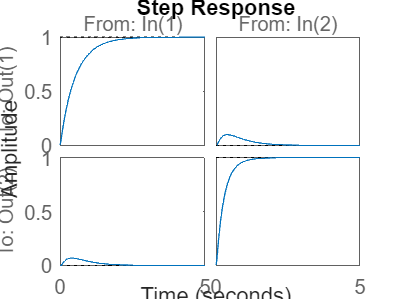

step(GLC)